# Estructuras de datos: Tablas

Las tablas son un tipo de datos adecuado para datos tabulares que a menudo se almacenan como columnas en un archivo de texto o en una hoja de cálculo. Las tablas constan de filas (**observaciones**) y columnas (**variables**).

**Figura 1.** Ilustración de una tabla en MATLAB.

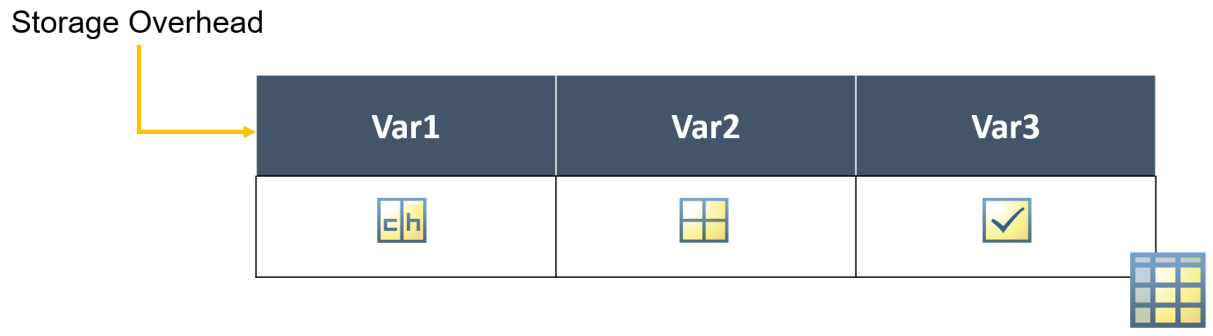

*Tomado de MATLAB Programming Techniques Quick Reference.*

**Cada variable en una tabla puede tener un tipo de datos diferente, la única restricción es que cada variable debe tener el mismo número de observaciones.**

Además, no está restringido que una variable sea de una sola columna. Es decir, una variable puede contener varias columnas, siempre y cuando todas estas tengan el mismo número de filas.

"Hola"

ans = "Hola"

'Hola'

ans = 'Hola'

## Crear una tabla

Las tablas dentro de MATLAB son de clase `table` y se pueden crear de distintas formas, aunque la más usual es ingresando las variables en la función `table`.

### Función `table`

La función `table` permite crear una tabla de distintas formas, pero la más común es ingresando las variables.

**Todas las variables deben tener el mismo número de filas.**

clear

% Crear algunas variables.
nombre = ["Arturo" "Isacc" "Génesis" "Elizabeth"]';
edad = [15 18 20 19]';
esExtranjero = logical([0 1 0 0]');

% Crear una tabla a través de variables.
T = table(nombre, edad, esExtranjero)

T = 4×3 table
      nombre       edad    esExtranjero
    ___________    ____    ____________

    "Arturo"        15        false    
    "Isacc"         18        true     
    "Génesis"       20        false    
    "Elizabeth"     19        false    


#### Observación

La visualización de una tabla dentro del live script es muy útil, no obstante, en bastante documentación también se encontrará la visualización de la ventana de comandos (la cual se replica utilizando la función `disp`), por ende se recomienda intentar familiarizarse con ambas formas, no sólo con una.

disp(T)

      nombre       edad    esExtranjero
    ___________    ____    ____________

    "Arturo"        15        false    
    "Isacc"         18        true     
    "Génesis"       20        false    
    "Elizabeth"     19        false    



Además, como se mencionó en la introducción, una variable puede tener más de una columna.

apellido = ["López" "Hidrobo" "Ramirez" "Blanco"]';
nombreCompleto = [nombre apellido];
T = table(nombreCompleto, edad, esExtranjero)

T = 4×3 table
         nombreCompleto         edad    esExtranjero
    ________________________    ____    ____________

    "Arturo"       "López"       15        false    
    "Isacc"        "Hidrobo"     18        true     
    "Génesis"      "Ramirez"     20        false    
    "Elizabeth"    "Blanco"      19        false    


disp(T)

         nombreCompleto         edad    esExtranjero
    ________________________    ____    ____________

    "Arturo"       "López"       15        false    
    "Isacc"        "Hidrobo"     18        true     
    "Génesis"      "Ramirez"     20        false    
    "Elizabeth"    "Blanco"      19        false    



### Función `array2table`

La función `array2table` permite convertir una matriz en una tabla.

clear

grades = [7 8 8 5
          8 8 6 4
          9 9 7 6]

grades =      7     8     8     5
     8     8     6     4
     9     9     7     6


T = array2table(grades)

T = 3×4 table
    grades1    grades2    grades3    grades4
    _______    _______    _______    _______

       7          8          8          5   
       8          8          6          4   
       9          9          7          6   


disp(T)

    grades1    grades2    grades3    grades4
    _______    _______    _______    _______

       7          8          8          5   
       8          8          6          4   
       9          9          7          6   



## Modificar las propiedades de una tabla

Para modificar las propiedades de una tabla se utiliza la notación punto, por lo que conviene detallarla antes.

La notación punto hace referencia a las variables de la tabla por nombre, `T.varname`, donde `T` es la tabla y `varname` es el nombre de la variable.

La notación punto se puede utilizar para indexar elementos, añadir o quitar elementos, etc.; pero también se puede utilizarla para acceder a las propiedades de la tabla: `Properties`.

clear

% Crear algunas variables.
nombre = ["Isacc" "Arturo" "Génesis" "Elizabeth"]';
edad = [18 17 20 19]';
esExtranjero = logical([1 0 0 0]');

% Crear una tabla a través de variables.
T = table(nombre, edad, esExtranjero)

T = 4×3 table
      nombre       edad    esExtranjero
    ___________    ____    ____________

    "Isacc"         18        true     
    "Arturo"        17        false    
    "Génesis"       20        false    
    "Elizabeth"     19        false    


% Acceder a las propiedades de la tabla.
T.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'nombre'  'edad'  'esExtranjero'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


Podemos modificar cualquiera de las propiedades de una tabla accediendo a éstas mediante la notación punto de nuevo. Las propiedades más usuales para modificar son el nombre de las variables `VariableNames` y el nombre de las observaciones `RowNames`.

% Visualización del nombre de las variables.
T.Properties.VariableNames

ans = 1×3 cell array
    {'nombre'}    {'edad'}    {'esExtranjero'}


% Modificar el nombre de las variables.
T.Properties.VariableNames = ["Nombre" "Edad" "Extranjero"]

T = 4×3 table
      Nombre       Edad    Extranjero
    ___________    ____    __________

    "Isacc"         18       true    
    "Arturo"        17       false   
    "Génesis"       20       false   
    "Elizabeth"     19       false   


% Modificar el nombre de las variables.
T.Properties.RowNames = ["001" "002" "003" "004"]

T = 4×3 table
             Nombre       Edad    Extranjero
           ___________    ____    __________

    001    "Isacc"         18       true    
    002    "Arturo"        17       false   
    003    "Génesis"       20       false   
    004    "Elizabeth"     19       false   


% Visualización de la tabla modificada.
disp(T)

             Nombre       Edad    Extranjero
           ___________    ____    __________

    001    "Isacc"         18       true    
    002    "Arturo"        17       false   
    003    "Génesis"       20       false   
    004    "Elizabeth"     19       false   



## Indexación de tablas

Para detallar la indexación de tablas primero se creará una con el MAT-file "patients.mat" que se encuentra dentro MATLAB como base de datos de ejemplo.

clear

% Crear algunas variables.
load patients.mat
whos

  Name                            Size            Bytes  Class      Attributes

  Age                           100x1               800  double               
  Diastolic                     100x1               800  double               
  Gender                        100x1             11412  cell                 
  Height                        100x1               800  double               
  LastName                      100x1             11616  cell                 
  Location                      100x1             14208  cell                 
  SelfAssessedHealthStatus      100x1             11540  cell                 
  Smoker                        100x1               100  logical              
  Systolic                      100x1               800  double               
  Weight                        100x1               800  double               



% Crear una tabla.
T = table(Age, Height, Weight, Smoker);

% Establecer los nombres de las observaciones.
T.Properties.RowNames = LastName;

% La función head permite ver las 8 primeras observaciones de una tabla.
disp(head(T))

                Age    Height    Weight    Smoker
                ___    ______    ______    ______

    Smith       38       71       176      true  
    Johnson     43       69       163      false 
    Williams    38       64       131      false 
    Jones       40       67       133      false 
    Brown       49       64       119      false 
    Davis       46       68       142      false 
    Miller      33       64       142      true  
    Wilson      40       68       180      false 



### Indexación por posición

La indexación por posición estudiada en el tema de matrices también es válida para trabajar con tablas utilizando el mismo concepto.

El resultado de la indexación también es una tabla.

% Extraer todas las variables de las primeras 4 filas.
T(1:4, :)

ans = 4×4 table
                Age    Height    Weight    Smoker
                ___    ______    ______    ______

    Smith       38       71       176      true  
    Johnson     43       69       163      false 
    Williams    38       64       131      false 
    Jones       40       67       133      false 


% Extraer todas las variables de las últimas 5 filas.
T(end-4:end, :)

ans = 5×4 table
                 Age    Height    Weight    Smoker
                 ___    ______    ______    ______

    Alexander    25       69       171      true  
    Russell      44       69       188      true  
    Griffin      49       70       186      false 
    Diaz         45       68       172      true  
    Hayes        48       66       177      false 


Aunque también es posible indexar por posición utilizando como índice de fila y columna el nombre de la observación y el nombre de la variable, respectivamente.

% Indexar utilizando los nombres de las observaciones/variables.
T("Adams", ["Age" "Height"])

ans = 1×2 table
             Age    Height
             ___    ______

    Adams    48       66  


% Indexar utilizando los nombres de las observaciones/variables.
T(["Allen" "Bailey"], :)

ans = 2×4 table
              Age    Height    Weight    Smoker
              ___    ______    ______    ______

    Allen     39       63       143      false 
    Bailey    38       68       130      false 


### Indexación utilizando los nombres de las variables

Cuando indexa usando la notación punto, hay dos formas de especificar una variable.

- **Por nombre, sin comillas.** Por ejemplo, `T.Nombres` extrae la variable "Nombres".

- **Por una expresión, donde la expresión está encerrada entre paréntesis después del punto.** Por ejemplo, `T.("Fecha de inicio")` especifica una variable denominada "Fecha de inicio".

Se utiliza la primera sintaxis cuando el nombre de una variable tabular también es un identificador válido de MATLAB. Es decir, cuando el nombre de la variable sigue las reglas para nombrar variables dentro de MATLAB (letras, números y guión bajo).

Por otra parte, se utiliza la segunda sintaxis cuando se especifica:

- Un número que indica la posición de la variable en la tabla.

- Un nombre de variable que no es un identificador válido de MATLAB.

- Cuando se agregan variables con identificadores no válidos de MATLAB.

Para explicar las indexaciones se utilizará la tabla creada anteriormente.

% Indexar la variable "Age".
T.Age

ans =     38
    43
    38
    40
    49
    46
    33
    40
    28
    31


% Indexar la variable en la posición 2 (corresponde a "Height").
T.(2)

ans =     71
    69
    64
    67
    64
    68
    64
    68
    68
    66


### Agregar/quitar variables a una tabla

Existen diferentes formas para agregar una variable a una tabla, pero la más común es utilizar la notación punto.

% Convertir la variable "Location" en una variable categórica.
Location = categorical(Location);

% Añadir una variable con la notación punto.
T.Location = Location;

% Visualizar las primeras observaciones.
head(T)

ans = 8×5 table
                Age    Height    Weight    Smoker            Location         
                ___    ______    ______    ______    _________________________

    Smith       38       71       176      true      County General Hospital  
    Johnson     43       69       163      false     VA Hospital              
    Williams    38       64       131      false     St. Mary's Medical Center
    Jones       40       67       133      false     VA Hospital              
    Brown       49       64       119      false     County General Hospital  
    Davis       46       68       142      false     St. Mary's Medical Center
    Miller      33       64       142      true      VA Hospit

Notemos que el nombre de la variable se encuentra determinado por el nombre del vector añadido. No obstante, si el nombre del vector no es que quisiéramos para nuestra nueva variable, entonces utilizamos la notación punto indicando el nombre entre paréntesis.

clear

% Crear algunas variables.
nombre = ["Arturo" "Isacc" "Génesis" "Elizabeth"]';
edad = [15 18 20 19]';
esExtranjero = logical([0 1 0 0]');

% Crear una tabla a través de variables.
T = table(nombre, edad, esExtranjero);
disp(T)

      nombre       edad    esExtranjero
    ___________    ____    ____________

    "Arturo"        15        false    
    "Isacc"         18        true     
    "Génesis"       20        false    
    "Elizabeth"     19        false    



% Crear una variable.
ubicacion = ["La Floresta" "Cumbayá" "La Floresta" "El Valle"]';

% Añadir una variable con caracteres especiales.
T.("Ubicación") = categorical(ubicacion);
disp(T)

      nombre       edad    esExtranjero     Ubicación 
    ___________    ____    ____________    ___________

    "Arturo"        15        false        La Floresta
    "Isacc"         18        true         Cumbayá    
    "Génesis"       20        false        La Floresta
    "Elizabeth"     19        false        El Valle   



Para quitar una table también se utiliza la notación punto, indexando la variable que se desea eliminar y asignándole la matriz vacía.

% Visualizar la tabla.
disp(T)

      nombre       edad    esExtranjero     Ubicación 
    ___________    ____    ____________    ___________

    "Arturo"        15        false        La Floresta
    "Isacc"         18        true         Cumbayá    
    "Génesis"       20        false        La Floresta
    "Elizabeth"     19        false        El Valle   



% Quitar una variable.
T.esExtranjero = [];
disp(T)

      nombre       edad     Ubicación 
    ___________    ____    ___________

    "Arturo"        15     La Floresta
    "Isacc"         18     Cumbayá    
    "Génesis"       20     La Floresta
    "Elizabeth"     19     El Valle   



#### Observación

La función `categorical` no fue estudiada previamente debido a que los arreglos categóricos (**categorical array**) son generalmente utilizados junto con tablas, más no de forma individual.

Además, para su uso se requiere conocimientos mínimos de estadística descriptiva para aprovecharlos al máximo. No obstante, de manera intuitiva se entiende que esta función convierte en categorías las cadenas o arreglos caracter.

Por otra parte, únicamente se ha detallado cómo indexar una variable, no varias (utilizando la notación punto). Para indexar varias variables se requiere conocer otro tipo de arreglo: las celdas (**cell array**). Sin embargo, este tipo de arreglos no se estudiarán en este curso debido a que su uso es más particular que general, no quitándole mucha utilidad en ciertos casos.

Cabe destacar que la mayoría de las veces se trabajan con datos tabulares, como el formato de una hoja de cálculo de Excel. Por lo tanto, la tablas son las indicadas en estas situaciones.

## Funciones para trabajar con tablas

Existen diversas funciones que están diseñadas para trabajar con tablas. A continuación se detallan las más usuales.

A continuación se trabajará con la siguiente tabla.

clear

% Crear algunas variables.
nombre = ["Arturo" "Isacc" "Génesis" "Elizabeth"]';
califMatematica = [8 7 8 7
                   9 7 8 8
                   8 8 8 8
                   7 6 8 7];
finalGrade = [7.5 8 8 7]';

% Crear una tabla a través de variables.
T = table(nombre, califMatematica, finalGrade);
T.Properties.VariableNames = ["Nombre" "Matemática" "Nota final"];

% Visualización de la tabla modificada.
disp(T)

      Nombre          Matemática       Nota final
    ___________    ________________    __________

    "Arturo"       8    7    8    7       7.5    
    "Isacc"        9    7    8    8         8    
    "Génesis"      8    8    8    8         8    
    "Elizabeth"    7    6    8    7         7    



### Funciones `width` y `height`

Para conocer el número de variables (o columnas) de una tabla se utiliza la función `width`, mientras que para conocer el número de observaciones (o filas) se utiliza la función `height`.

Es decir, en lugar de utilizar la función `size` o `length` para determinar las dimensiones de una tabla, se utilizan las funciones previamente mencionadas.

% Determinar el número de variables.
width(T)

ans = 3

% Determinar el número de observaciones.
height(T)

ans = 4

### Funciones `head` y `tail`

La función `head`, que ya se utilizó previamente, permite visualizar las *k-ésimas* primeras observaciones. Por defecto $k$ es igual a 8.

% Visualizar las primeras 8 observaciones.
head(T)

ans = 4×3 table
      Nombre          Matemática       Nota final
    ___________    ________________    __________

    "Arturo"       8    7    8    7       7.5    
    "Isacc"        9    7    8    8         8    
    "Génesis"      8    8    8    8         8    
    "Elizabeth"    7    6    8    7         7    


Evidentemente la función `head` mostrará las primeras 8 observaciones siempre que la tabla las tenga, caso contrario mostrará todas las que haya.

% Visualizar las primeras 4 observaciones.
head(T, 2)

ans = 2×3 table
     Nombre        Matemática       Nota final
    ________    ________________    __________

    "Arturo"    8    7    8    7       7.5    
    "Isacc"     9    7    8    8         8    


Por otra parte, la función `tail` permite visualizar las últimas *k-ésimas* observaciones. Por defecto $k$ es igual a 8.

% Visualizar las últimas 8 observaciones.
tail(T)

ans = 4×3 table
      Nombre          Matemática       Nota final
    ___________    ________________    __________

    "Arturo"       8    7    8    7       7.5    
    "Isacc"        9    7    8    8         8    
    "Génesis"      8    8    8    8         8    
    "Elizabeth"    7    6    8    7         7    


Evidentemente la función `tail` mostrará las últimas 8 observaciones siempre que la tabla las tenga, caso contrario mostrará todas las que haya.

% Visualizar las últimas 3 observaciones.
tail(T, 2)

ans = 2×3 table
      Nombre          Matemática       Nota final
    ___________    ________________    __________

    "Génesis"      8    8    8    8        8     
    "Elizabeth"    7    6    8    7        7     


### Función `movevars`

La función `movevars` permite mover las variables de una tabla. A continuación se muestra una imagen de cómo se realiza esto.

**Figura 2.** Visualización de cómo trabaja la función `movevars`.

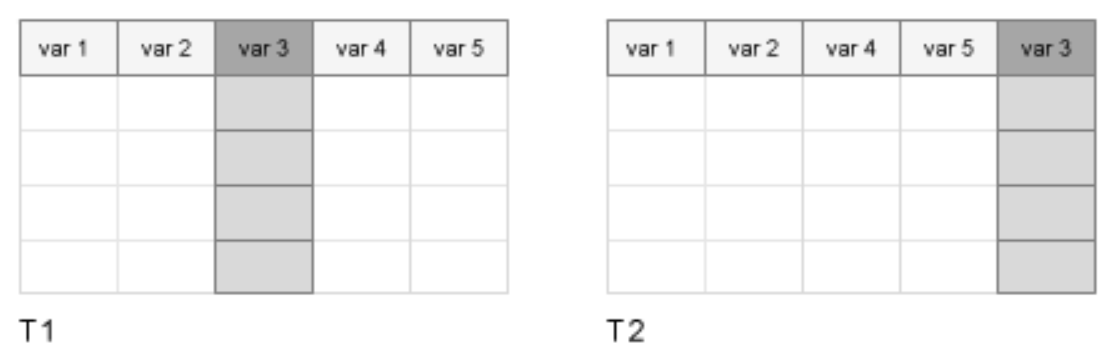

*Tomado de *[*MathWorks: *`movevars`](https://www.mathworks.com/help/matlab/ref/table.movevars.html)*.*

`A continuación se muestra un ejemplo de esto.`

disp(T)

      Nombre          Matemática       Nota final
    ___________    ________________    __________

    "Arturo"       8    7    8    7       7.5    
    "Isacc"        9    7    8    8         8    
    "Génesis"      8    8    8    8         8    
    "Elizabeth"    7    6    8    7         7    



% Mover la variable "Nota final" después de la variable "Nombre".
newT1 = movevars(T, "Nota final", "After", "Nombre")

newT1 = 4×3 table
      Nombre       Nota final       Matemática   
    ___________    __________    ________________

    "Arturo"          7.5        8    7    8    7
    "Isacc"             8        9    7    8    8
    "Génesis"           8        8    8    8    8
    "Elizabeth"         7        7    6    8    7


% Mover la variable "Nota final" antes de la variable "Matemática".
newT2 = movevars(T, "Nota final", "After", "Nombre")

newT2 = 4×3 table
      Nombre       Nota final       Matemática   
    ___________    __________    ________________

    "Arturo"          7.5        8    7    8    7
    "Isacc"             8        9    7    8    8
    "Génesis"           8        8    8    8    8
    "Elizabeth"         7        7    6    8    7


## Realizar cálculos con tablas

Hasta este momento se ha realizado diferentes ejercicios y ejemplos utilizando funciones para clases numéricas (enteros y decimales), cadenas y arreglos caracter, y para valores lógicos.

Entonces es posible reasignar a una variable la misma variable modificada (aplicando algún cálculo, función, etc.), o simplemente creando una variable a partir de otras variables.

clear

% Crear algunas variables.
nombre = ["Arturo" "Isacc" "Génesis" "Elizabeth"]';
califMatematica = [8 5 3 7
                   9 6 5 8
                   9 7 8 8
                   8 9 6 7];

% Crear una tabla a través de variables.
T = table(nombre, califMatematica);
T.Properties.VariableNames = ["Nombre" "Matemática"];

% Crear una variable a partir de otra variable.
T.("Nota máxima") = max(T.("Matemática"), [], 2);
T.("Nota final") = mean(T.("Matemática"), 2);

% Visualización de la tabla modificada.
disp(T)

      Nombre          Matemática       Nota máxima    Nota final
    ___________    ________________    ___________    __________

    "Arturo"       8    5    3    7         8            5.75   
    "Isacc"        9    6    5    8         9               7   
    "Génesis"      9    7    8    8         9               8   
    "Elizabeth"    8    9    6    7         9             7.5   



#### Observación

La función `mean` es similar a la función `max` o `min`, sólo que en lugar de obtener el número máximo o mínimo, respectivamente, se obtendrá la media artimética, o promedio, por filas.

## Material adicional

- [Tablas](https://www.mathworks.com/help/matlab/tables.html)

- [Ventajas de usar tablas](https://www.mathworks.com/help/matlab/matlab_prog/advantages-of-using-tables.html)

- [Crear tablas y asignarles información](https://www.mathworks.com/help/matlab/matlab_prog/create-a-table.html)

- [Acceder a información de una tabla](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

- [Agregar, eliminar y reorganizar variables de tabla](https://www.mathworks.com/help/matlab/matlab_prog/add-and-delete-table-variables.html)

- [Cálculos en tablas](https://www.mathworks.com/help/matlab/matlab_prog/calculations-on-tables.html)

- [Modificar unidades, descripciones y nombres de variables de tabla](https://www.mathworks.com/help/matlab/matlab_prog/modify-units-descriptions-and-table-variable-names.html)

- [Conjuntos de datos de muestra](https://www.mathworks.com/help/stats/sample-data-sets.html)